
$$\begin{array}{l}
\mathrm{Avem}\;3\;\mathrm{puncte}\;\mathrm{și}\;\mathrm{valoarea}\;\mathrm{funcției}\;\mathrm{în}\;\mathrm{acele}\;\mathrm{puncte}:f\left(-1\right)=-1^3 =-1,f\left(0\right)=0^3 ,f\left(1\right)=1^3 =1\\
\mathrm{Forma}\;\mathrm{pentru}\;\mathrm{spline}-\mathrm{ul}\;\mathrm{cubic}:S_i \left(x\right)=a_i +b_i \left(x-x_i \right)+c_i {\left(x-x_i \right)}^2 +d_i {\left(x-x_i \right)}^3 \\
\mathrm{Apoi}\;\mathrm{avem}\;\mathrm{condiții}\;\mathrm{de}\;\mathrm{continuitate}:\\
S_{j+1} \left(x_{j+1} \right)=S_j \left(x_{j+1} \right)\;\mathrm{oricare}\;\mathrm{ar}\;\mathrm{fi}\;0\le j\le n-2\\
{S_{j+1} }^{\prime } \left(x_{j+1} \right)={S_j }^{\prime } \left(x_{j+1} \right)\;\mathrm{oricare}\;\mathrm{ar}\;\mathrm{fi}\;0\le j\le n-2\\
{{S_{j+1} }^{\prime } }^{\prime } \left(x_{j+1} \right)={{S_j }^{\prime } }^{\prime } \left(x_{j+1} \right)\;\mathrm{oricare}\;\mathrm{ar}\;\mathrm{fi}\;0\le j\le n-2\\
\mathrm{și}\;\mathrm{condițiile}\;\mathrm{pentru}\;\mathrm{spline}\;\mathrm{natural}:\\
{{S_j }^{\prime } }^{\prime } \left(x_1 \right)=0\;\mathrm{și}\;{{S_j }^{\prime } }^{\prime } \left(x_n \right)=0
\end{array}$$


close all;
clear;
f = @(x)(x.^3);
t = [-1, 0, 1];

coef = spline_cubic(t, f(t),2);
disp("Coeficientii:");

Coeficientii:


coef

coef =      0     0     1    -1
     0     0     1     0


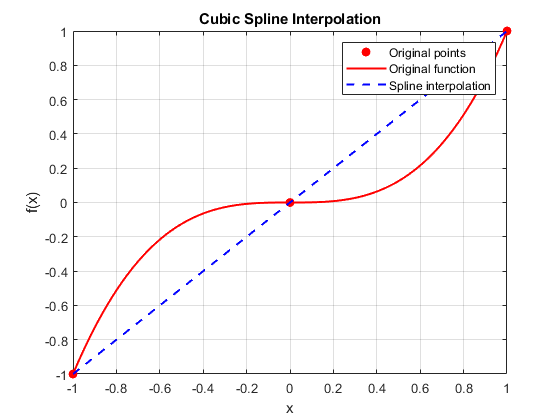


xx = linspace(-1, 1, 100);
sp = eval_spline_c(t, coef, xx);

figure;
plot(t, f(t), 'ro', 'MarkerFaceColor', 'r');
hold on;
plot(xx, f(xx), 'r-', 'LineWidth', 1.5);
plot(xx, sp, 'b--', 'LineWidth', 1.5);
legend('Original points', 'Original function', 'Spline interpolation');
xlabel('x');
ylabel('f(x)');
title('Cubic Spline Interpolation');
grid on;


% nu este spline propriu zis deoarece atat la s1(x) cat si la s2(x)
% avem coeficientii 0 pentru x^3, deci functiile obtinute care interpoleaza
% sunt liniare, nu cubice

function [c, md]=spline_cubic(x,f,type,der)
    %NATURAL SPLINE
    if (nargin<4) || (type==2), der=[0,0]; end

    n=length(x);
    if any(diff(x)<0), [x,ind]=sort(x); 
    else ind=1:n; end 
    
    y=f(ind); x=x(:); y=y(:);


    dx=diff(x); 
    diff(y');
    diff(y);
    ddiv=diff(y)./dx; 
    ds=dx(1:end-1); dd=dx(2:end); 
    dp=2*(ds+dd);                 
    md=3*(dd.*ddiv(1:end-1)+ds.*ddiv(2:end));
    switch type
        
    %COMPLETE SPLINE
    case 0                                       
        dp1=1; dpn=1; vd1=0; vdn=0;
        md1=der(1); mdn=der(2);
    %D2 SI NORMAL
    case {1,2}
        dp1=2; dpn=2; vd1=1; vdn=1;
        md1=3*ddiv(1)-0.5*dx(1)*der(1);
        mdn=3*ddiv(end)+0.5*dx(end)*der(2);
    %DEBOOR SPLINE
    case 3 
        x31=x(3)-x(1);xn=x(n)-x(n-2);
        dp1=dx(2); dpn=dx(end-1);
        vd1=x31;
        vdn=xn;
        md1=((dx(1)+2*x31)*dx(2)*ddiv(1)+dx(1)^2*ddiv(2))/x31;
        mdn=(dx(end)^2*ddiv(end-1)+(2*xn+dx(end))*dx(end-1)*ddiv(end))/xn;
    end
    
    %construire sistem rar
    dp=[dp1;dp;dpn];
    dp1=[0;vd1;dd];
    dm1=[ds;vdn;0];
    md=[md1;md;mdn];
    A=spdiags([dm1,dp,dp1],-1:1,n,n);
    m=A\md;
    c(:,4)=y(1:end-1);
    c(:,3)=m(1:end-1);
    c(:,1)=(m(2:end)+m(1:end-1)-2*ddiv)./(dx.^2);
    c(:,2)=(ddiv-m(1:end-1))./dx-dx.*c(:,1);
end

.

%EVALSPLINE - compute cubic spline value
%call z=evalspline(x,c,t)
%x - nodes (knots)
%t - evaluation points 
%c - coefficients length(x)-1 by 4 matrix
%z - values
function z=eval_spline_c(x,c,t)
    n=length(x);
    x=x(:); t=t(:); 
    k = ones(size(t));
    
    %cauta un interval pt t in nodurile spline-ului
    for j = 2:n-1
        k(x(j) <= t) = j;
    end

    % interpolant eval.
    s = t - x(k); 
    z = c(k,4) + s.*(c(k,3) + s.*(c(k,2) + s.*c(k,1)));
end